初始化

%mm
R = 80;
r = 80;
L1 = 160;
L2 = 192; 
toolHight = 132;

RRS_2RRU = RRS_2RRU_Basic(R, r, L1, L2, toolHight);

%simulink multibody


%simulink 导入模型关节角定义偏差
offsetThetaSim = @(theta) [pi-theta(1), theta(2), -theta(3)-pi/2];

1.测试逆运动学模块

P_pose = [193.46, 0, 0]; %[z_p, alpha, beta]
[Tf_BTC, Tf_P] = RRS_2RRU.calEndEffectorSE3(P_pose(1), P_pose(2), P_pose(3));
thetas = RRS_2RRU.invKineUpdate(Tf_BTC); %invkine
rad2deg(thetas)

ans =    24.9997  155.0003   24.9997


thetas_sim = offsetThetaSim(thetas); %thetas in simulink multibody
rad2deg(thetas_sim)

ans =   155.0003  155.0003 -114.9997


2.测试逆向静力学模块

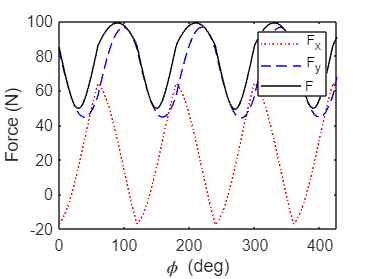

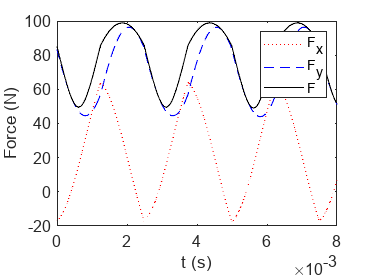

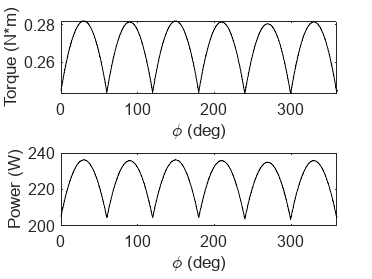

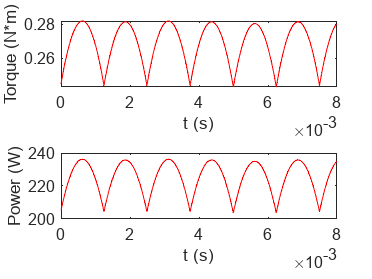

% 参数
Ks=791;
beta=71.6;
a_p = 1;
feedRate = 50; %mm/s
d = 6;
Nt = 3;
omega = 8000;

% 理论交变切削力
[Force_x, Force_y, Force, Torque, Power, t, phi] = getSlotMillingForce(Ks, beta, a_p, ...
                                                    feedRate, d, Nt, omega, 1000);

F_max = max(Force);

% 经验公式切削力
F_c = roughMillingForce(feedRate, Nt, d, a_p, d, omega);

% 修正交变力
k_m = F_c/F_max;
Force_x_m = k_m*Force_x;
Force_y_m = k_m*Force_y;
Force_m = k_m*Force;
Torque_m = k_m*Torque;
Power_m = k_m*Power;

save related_params_verification\milling_force.mat Power_m Torque_m...
    Force_y_m Force_x_m Force_m t phi -mat;

save related_params_verification\power.mat t Power_m -mat
save related_params_verification\torque.mat t Torque_m -mat
save related_params_verification\force_y.mat t Force_y_m -mat
save related_params_verification\force_x.mat t Force_x_m -mat
save related_params_verification\force.mat t Force_m -mat

3.测试指标